# Лабораторная работа №3 по СУвЭ

## Параметрический синтез и исследование цифровой системы управления с И-регулятором и объектом в виде последовательно включенных апериодического и интегрирующего звеньев из условия обеспечения заданного переходного процесса.

Определяем вариант задания:

ob.R = 10+unifrnd(-1,1);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = ob.Ce;
save('data.mat', 'ob');

## Задание 1

Моделирование И-регулятора

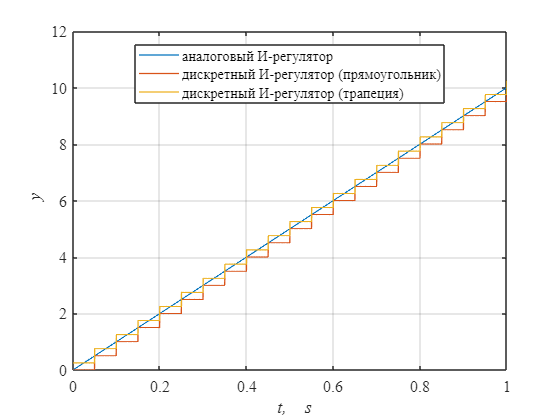

an.Ki = 10;%аналогавая система
dsc.Ki = 10;%дискретная система

Tmdl = 1;
To = 0.05;
warning off
simNew = sim('lab3_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.y(:,1);
an.y = simNew.y(:,2);
dsc_pr.y = simNew.y(:,3);
dsc_tr.y = simNew.y(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'Linewidth', 1)
hold on
grid on
plot(t,dsc_pr.y,'Linewidth', 1)
plot(t,dsc_tr.y,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y')
legend('аналоговый И-регулятор', 'дискретный И-регулятор (прямоугольник)', 'дискретный И-регулятор (трапеция)', Location='best')

## Задание 2

#### Синтез системы управления с использованием И-регулятора

syms Tu L R s

Передаточная функция электрической части привода постоянного тока

crl.Wob = 1/(L*s+R);

Передаточная функция разомкнутой системы, настроенной на технический оптиум

Tu = L/R;
crl.Wol = 1/(2*Tu*s*(Tu*s+1))

crl = struct with fields:
       Wob: 1/(R + L*s)
       Wol: R/(2*L*s*((L*s)/R + 1))
        Tu: 0.0021
       Kia: 2.5879e+06
       Kid: 2.5879e+06
        Tz: 0.0054
    Kia_mA: 0.0020
    Kid_mA: 0.0020


передаточная функция регулятора

Wreg = crl.Wol/(crl.Wob);
disp(collect(Wreg, s))

$$\frac{R^{2}}{\left(2\,L\right)\,s}$$

#### Моделирование работы системы, настроенной на тех. оптиум

To=0.1*Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.03;

To=0.1*crl.Tu;

warning off
simNew = sim('lab3_2my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_2my/Gain2
lab3_2my/Gain4
lab3_2my/I tr/Gain6
lab3_2my/I tr/Sum2
lab3_2my/I tr/Gain5
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_

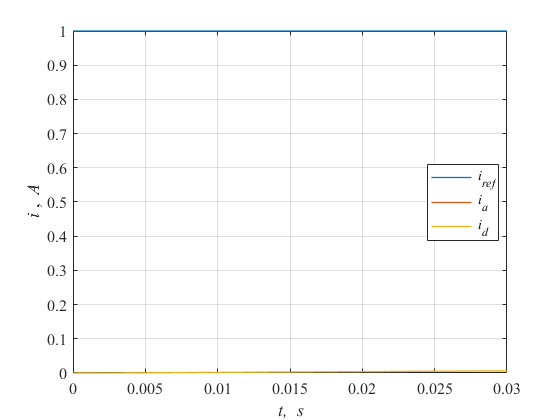

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 13.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 13.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


To=Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.03;

To=crl.Tu;

warning off
simNew = sim('lab3_2my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_2my/Gain2
lab3_2my/Gain4
lab3_2my/I tr/Gain6
lab3_2my/I tr/Sum2
lab3_2my/I tr/Gain5
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_

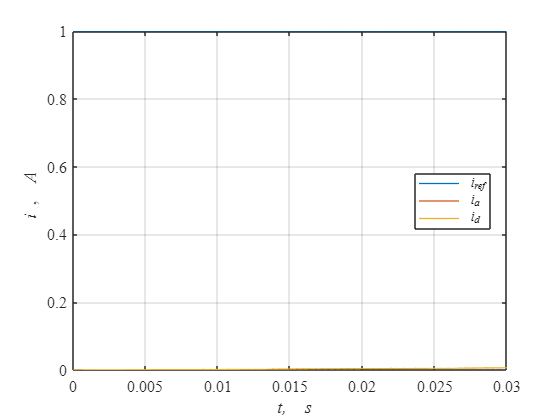

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 13.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 13.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


## Задание 3. Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки ε = 0

clear Tzap f
To=crl.Tu

To = 0.0022


for i = 1:10
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_3my.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


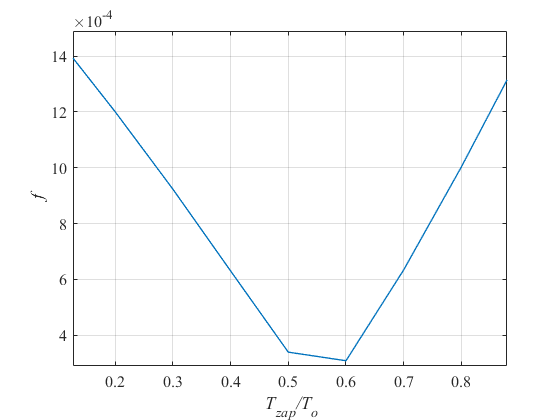

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

xlim([0.127 0.879])
ylim([0.00029 0.00149])

#### Перенастройка с помощью метода переоборудования

#### To=Tt

Tmdl = 0.05;
To=1*ob.L/ob.R;
crl.Tz = 0.6*To;
crl.Tu = ob.L/ob.R + crl.Tz

crl = struct with fields:
       Wob: 1/(R + L*s)
       Wol: R/(2*L*s*((L*s)/R + 1))
        Tu: 0.0035
       Kia: 2.1811e+03
       Kid: 2.1811e+03
        Tz: 0.0013
    Kia_mA: 0.0020
    Kid_mA: 0.0020



crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


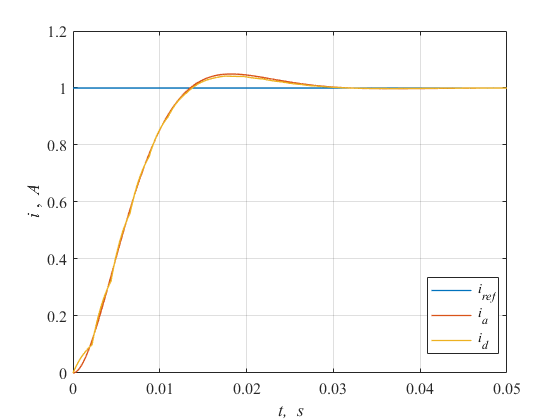

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.4*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.2*Tu 


#### To=2*Tt

Tmdl = 0.05;
To=2*ob.L/ob.R;
crl.Tz = 0.55*To;
crl.Tu = ob.L/ob.R + crl.Tz

crl = struct with fields:
       Wob: 1/(R + L*s)
       Wol: R/(2*L*s*((L*s)/R + 1))
        Tu: 0.0046
       Kia: 1.3632e+03
       Kid: 1.3632e+03
        Tz: 0.0024
    Kia_mA: 0.0020
    Kid_mA: 0.0020



crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


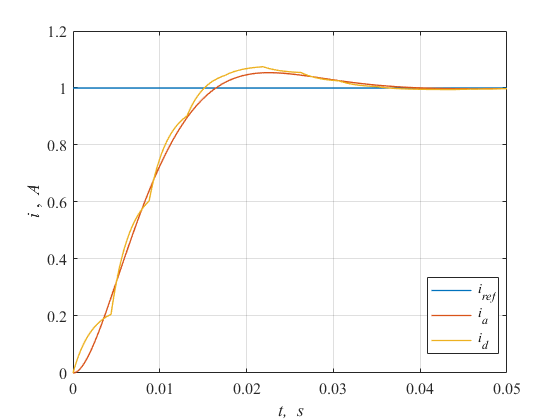

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.0*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.8*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 7.7*Tu 


## Задание 4

Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки                               

clear Tzap f
To=ob.L/ob.R

To = 0.0022

Tmdl = 0.05

Tmdl = 0.0500

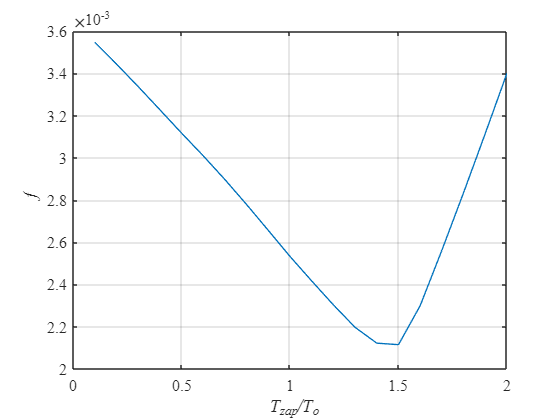


for i = 1:20
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_4my.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end
h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

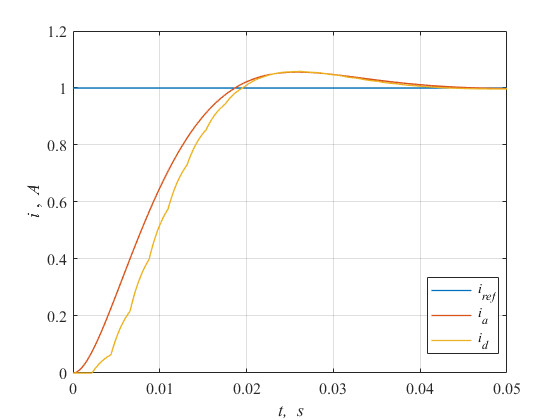

Tmdl = 0.05;
To=1*ob.L/ob.R;
crl.Tz = 1.45*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_4my.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.3*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.6*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 6.2*Tu 


#### To=2*Tt

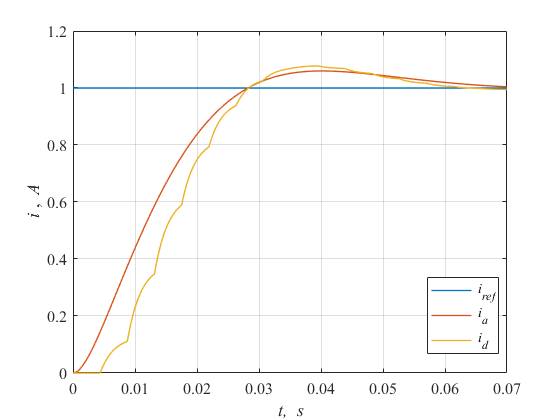

Tmdl = 0.07;
To=2*ob.L/ob.R;
crl.Tz = 1.45*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(2*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_4my.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.7*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 8.3*Tu 


## Задание 5

#### 2. Синтез системы управления с использованием И-регулятора

syms Tu L R s

Передаточная функция электрической части привода постоянного тока

crl.Wob = 1/(L*s+R);

Передаточная функция разомкнутой системы, настроенной на биномиальный оптиум

Tu = L/R;
crl.Wol = 1/(3*Tu*s*(Tu*s+1))

crl = struct with fields:
       Wob: 1/(R + L*s)
       Wol: R/(3*L*s*((L*s)/R + 1))
        Tu: 0.0085
       Kia: 559.2690
       Kid: 559.2690
        Tz: 0.0064
    Kia_mA: 0.0020
    Kid_mA: 0.0020


передаточная функция регулятора

Wreg = crl.Wol/(crl.Wob);
disp(collect(Wreg, s))

$$\frac{R^{2}}{\left(3\,L\right)\,s}$$

#### Моделирование работы системы, настроенной на тех. оптиум

To=0.1*Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.03;

To=0.1*crl.Tu;

warning off
simNew = sim('lab3_2my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_2my/Gain2
lab3_2my/Gain4
lab3_2my/I tr/Gain6
lab3_2my/I tr/Sum2
lab3_2my/I tr/Gain5
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_

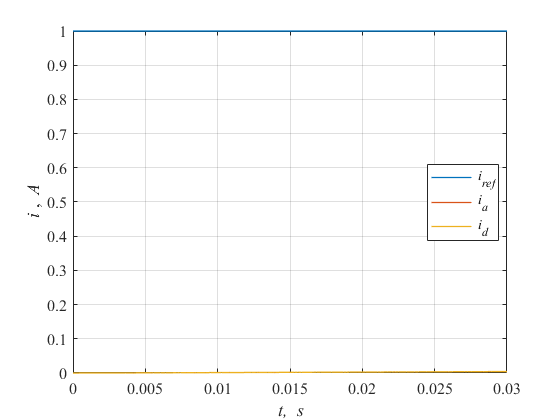

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 13.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 13.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


To=Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.03;

To=crl.Tu;

warning off
simNew = sim('lab3_2my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_2my/Gain2
lab3_2my/Gain4
lab3_2my/I tr/Gain6
lab3_2my/I tr/Sum2
lab3_2my/I tr/Gain5
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_

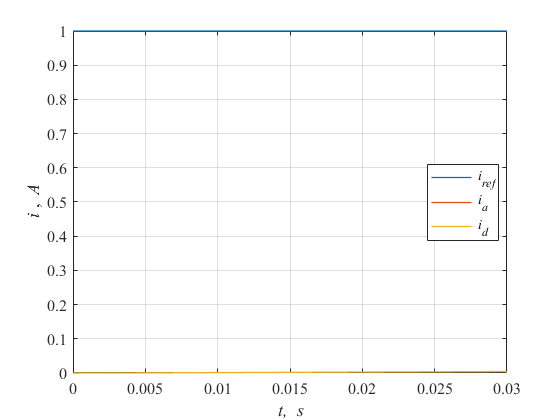

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 13.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 13.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### 3. Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки ε = 0

clear Tzap f
To=crl.Tu

To = 0.0022


for i = 1:10
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_3my.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


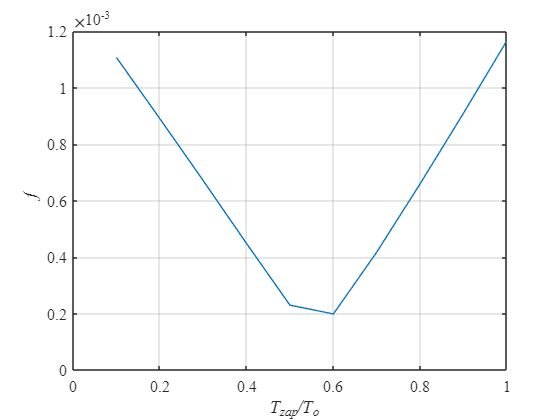

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

Tmdl = 0.05;
To=1*ob.L/ob.R;
crl.Tz = 0.6*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


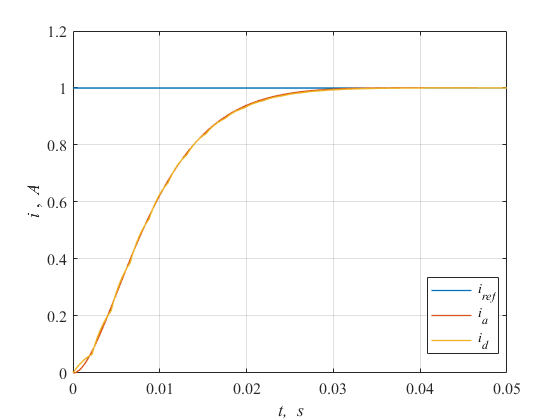

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 6.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.0*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### To=2*Tt

Tmdl = 0.05;
To=2*ob.L/ob.R;
crl.Tz = 0.55*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3my/Gain4
lab3_3my/I tr/Gain6
lab3_3my/I tr/Sum2
lab3_3my/I tr/Gain5
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_3my/ob1/DC motor/PS-Simulink Converter/EVAL_KEY/RESHAPE


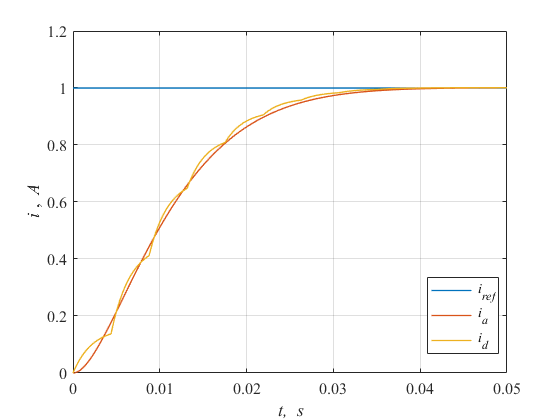

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 5.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.4*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки                               

clear Tzap f
To=ob.L/ob.R

To = 0.0022

Tmdl = 0.05

Tmdl = 0.0500

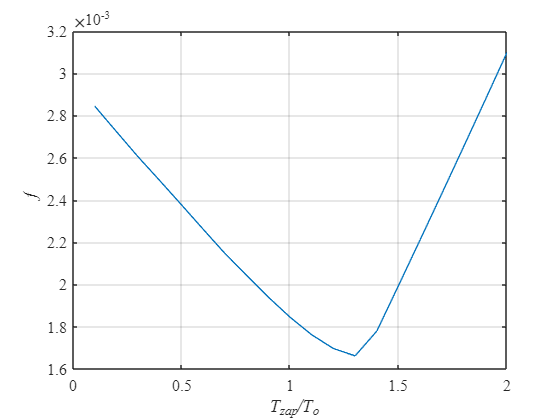


for i = 1:20
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_4my.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end
h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

Tmdl = 0.05;
To=1*ob.L/ob.R

To = 0.0022

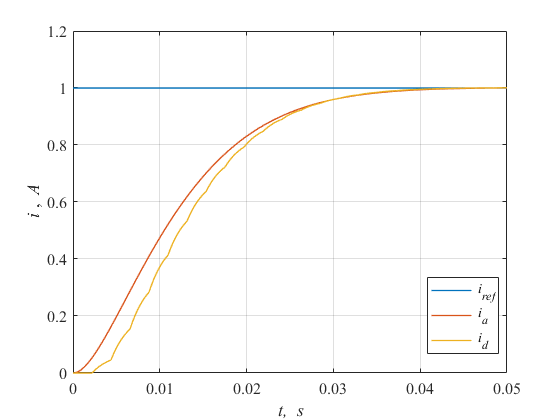

crl.Tz = 1.3*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_4my.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 5.7*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.7*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


#### To=2*Tt

Tmdl = 0.07;
To=2*ob.L/ob.R

To = 0.0044

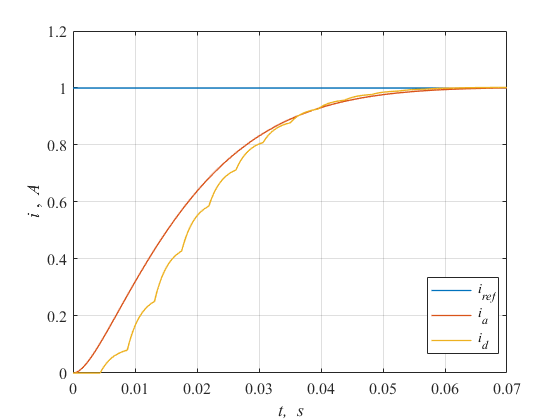

crl.Tz = 1.3*To;
crl.Tu = ob.L/ob.R + crl.Tz;

crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_4my.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 5.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.3*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 0.0*Tu 


## Задание 

Лаб 3. Вы синтезировали регулятор контура тока. Как изменится настройка системы управления, если датчик тока тоже будет измерять ток в мА. Привести формулы для вычисления новых коэффициентов регулятора и графики переходных процессов

syms Tu L R s

Передаточная функция электрической части привода постоянного тока

crl.Wob = (1/(L*s+R))/1000;

Передаточная функция разомкнутой системы, настроенной на технический оптиум

Tu = L/R;
crl.Wol = 1/(2*Tu*s*(Tu*s+1))

crl = struct with fields:
    Wob: 1/(1000*(R + L*s))
    Wol: R/(2*L*s*((L*s)/R + 1))


передаточная функция регулятора

Wreg = crl.Wol/(crl.Wob);
disp(collect(Wreg, s))

$$\frac{500\,R^{2}}{L\,s}$$

crl.Tu = ob.L/ob.R;
crl.Kia = 500*ob.R/(crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.04;

To=0.1*crl.Tu;

warning off
simNew = sim('lab3_2my.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_2my/Gain2
lab3_2my/Gain4
lab3_2my/I tr/Gain6
lab3_2my/I tr/Sum2
lab3_2my/I tr/Gain5
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_2my/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3_

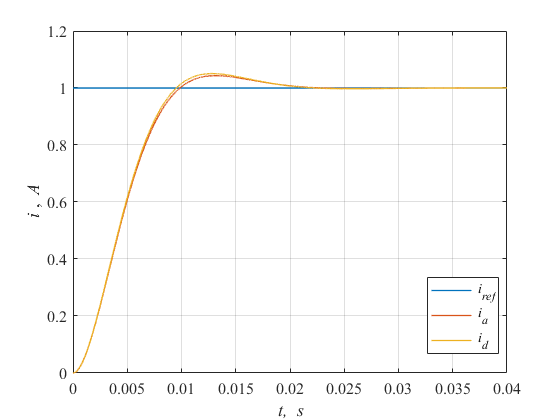

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Синтез

for i = 1:10
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_3_extra.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end

Found algebraic loop containing: 
lab3_3_extra/Gain2
lab3_3_extra/Gain4
lab3_3_extra/I tr/Gain6
lab3_3_extra/I tr/Sum2
lab3_3_extra/I tr/Gain5
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0


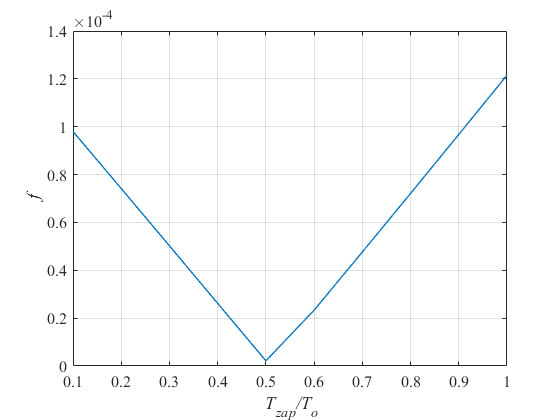

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Перенастройка с помощью метода переоборудования

#### To=Tt

Tmdl = 0.05;
To=1*ob.L/ob.R;
crl.Tz = 0.5*To;
crl.Tu = ob.L/ob.R + crl.Tz

crl = struct with fields:
    Wob: 1/(1000*(R + L*s))
    Wol: R/(2*L*s*((L*s)/R + 1))
     Tu: 0.0031
    Kia: 2.5879e+06
    Kid: 2.5879e+06
     Tz: 0.0010



crl.Kia = 500*ob.R/(crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3_extra.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3_extra/Gain2
lab3_3_extra/Gain4
lab3_3_extra/I tr/Gain6
lab3_3_extra/I tr/Sum2
lab3_3_extra/I tr/Gain5
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0


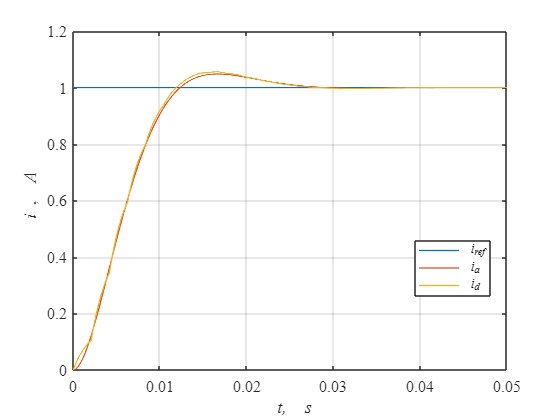

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.7*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 5.6*Tu 
